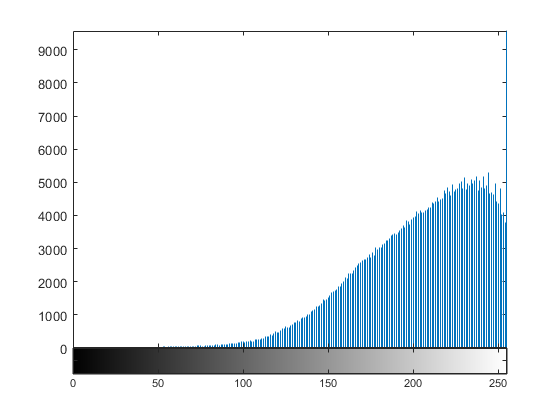

% DisplayAllImages();
im = imread("images/starfish_noise9.jpg");
% im = im * 1.05; % RIght skew to norma; dist.
imhist(im)

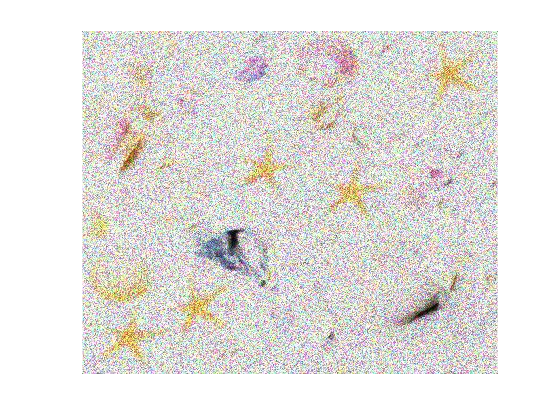

imshow(im)

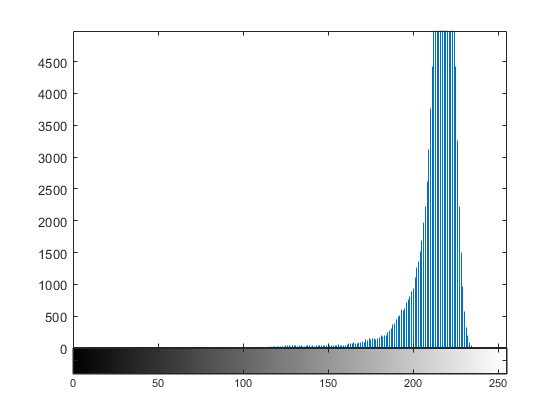

im = medfilt3(im, [5 5 5]);
im = imgaussfilt(im, 2);
[c1,c2,c3] = imsplit(im);
imhist(c1)

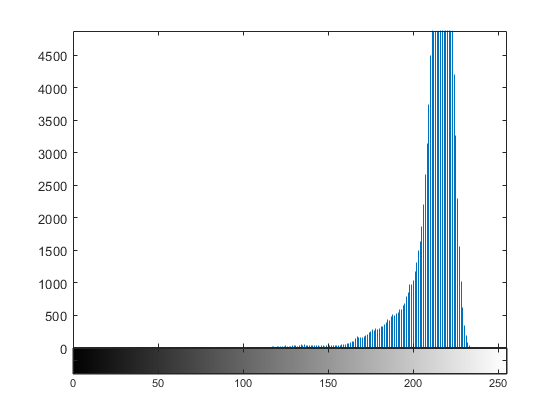

imhist(c2)

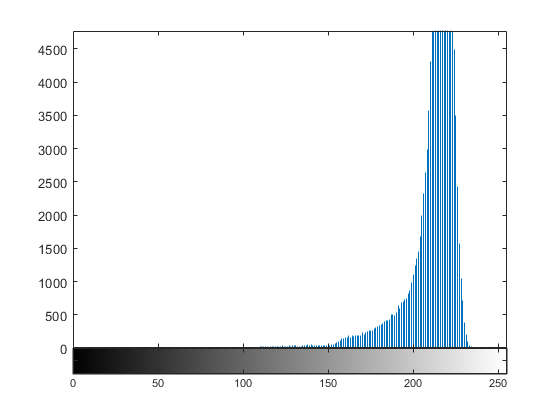

imhist(c3)

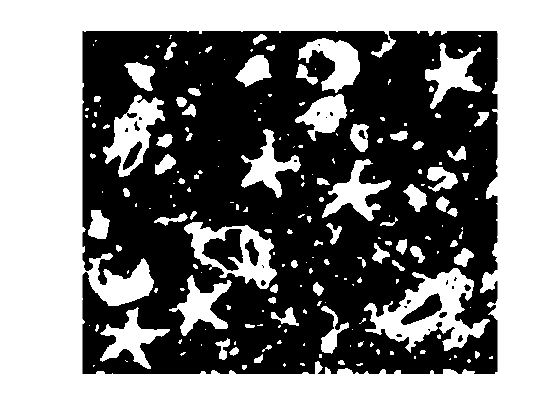

c3 = imadjust(c3); % Increase contrast
imP = c2 > 160 & c2 < 210;
% imP = HistThresh(im, 0, 6000, 0, 6000, 0, 6000);
imshow(imP)

function filepaths = GetFilesInSubDir(subDir)
    files = dir(subDir);
    files = files(~ismember({files.name}, {'.', '..'})); % Remove navigation elements from struct.
    files = files(contains({files.name}, {'starfish.', 'starfish_map', 'starfish_noise'})); % Get basic images only.
    filepaths = subDir + "\" + {files.name};
end

function DisplayAllImages()
    files = GetFilesInSubDir("images");
    
    for i = 1:numel(files)
        filepath = files(i);
        
        disp(filepath)
        
        im = imread(filepath);
%         imG = rgb2gray(im);
        im = medfilt3(im, [5 5 5]);
        im = imgaussfilt(im, 3);
        [c1,c2,c3] = imsplit(im);
        c1 = imadjust(c1);
        c2 = imadjust(c2);
        c3 = imadjust(c3);
        
%         figure
%         imshow(im)
        figure
        subplot(2,3,1)
        imshow(c1)
        subplot(2,3,2)
        imshow(c2)
        subplot(2,3,3)
        imshow(c3)
        subplot(2,3,4)
        imhist(c1, 50)
        subplot(2,3,5)
        imhist(c2, 50)
        subplot(2,3,6)
        imhist(c3, 50)
    end
end

function returnImg = HistThresh(img, ch1Min, ch1Max, ch2Min, ch2Max, ch3Min, ch3Max)
        % Create mask based on chosen histogram thresholds
        imgMask = (img(:,:,1) >= ch1Min ) & (img(:,:,1) <= ch1Max) & (img(:,:,2) >= ch2Min ) & (img(:,:,2) <= ch2Max) & (img(:,:,3) >= ch3Min ) & (img(:,:,3) <= ch3Max);
            
        % Set background pixels where BW is false to zero.
        figure
        img = img(repmat(imgMask,[1 1 3])) == 0;
        
        returnImg = img;
end